# Cell_morphology.mlx

% ==================================================================

%  Copyright © 2023-2025 Xiaofeng Dai (xiaofend@umich.edu)

%  SPDX-License-Identifier: GPL-3.0-or-later

%

%  This program is free software: you can redistribute it and/or modify

%  it under the terms of the GNU General Public License as published by

%  the Free Software Foundation, either version 3 of the License, or

%  (at your option) any later version.

%

%  This program is distributed in the hope that it will be useful,

%  but WITHOUT ANY WARRANTY; without even the implied warranty of

%  MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the

%  GNU General Public License for more details.

%

%  You should have received a copy of the GNU General Public License

%  along with this program (LICENSE file in the repository root).

%  If not, see <https://www.gnu.org/licenses/>.

%

%  Tested with: MATLAB R2024a and R2022a

% ==================================================================

### Morphology Analysis of Cell masks from Segmentation Results

% --------------------------------

% This live script loads phase‑contrast segmentation masks and single‑cell

% tracking results from ".fits.mat" and "PhaseMask.mat" files.

% It computes geometric properties (long/short axes, aspect ratio, cell area) 

% for every detected cell, aggregates results across multiple ROIs, and visualizes

% the distributions.

% -------------------------------------------------------------------------

### Select data directory & files

Filefolder=uigetdir('Example_Folder/subfolder');
Fitsname=uigetfile([Filefolder,filesep,'*fits.mat'],'MultiSelect','on');
Maskname=uigetfile([Filefolder,filesep,'*PhaseMask.mat'],'MultiSelect',"on");
Num_file=length(Fitsname);      % number of fields‑of‑view

Store_Mask=cell(Num_file,1);
Store_tracks=cell(Num_file,1);

% Load tracking structures and phase‑contrast masks in parallel (parfor)
parfor i=1:Num_file
    fitsname=Fitsname{i};
    fitspath=[Filefolder,filesep,fitsname];
    track = load(fitspath,'tracks');
    Store_tracks{i} = track.tracks;
    maskname=Maskname{i};
    maskpath=[Filefolder,filesep,maskname];
    mask = load(maskpath);
    Store_Mask{i} = mask.PhaseMask;
end

test = zeros(length(Store_Mask),1);
for i=1:length(Store_Mask)
    ind = max(max(Store_Mask{i}));
    test(i) = ind;
end
sum(test)   % total cell count across all ROIs

ans = 1777


clear i fitsname fitspath track maskname maskpath mask test

### Morphology Analysis

remeber to set up pixel size based on the camera you used.

*'feretProperties' is a customize function by Steve Eddins from MathWork, the helper functions can be found **here* *(steve's feret diameter)**.*

pixel_size=49; % nm per pixel
num_roi=Num_file;
Result_Filter=cell(num_roi,1);

parfor i=1:num_roi
    mask=Store_Mask{i};
    num_cell=max(mask,[],"all");
    result=zeros(num_cell,5);   %[cell_id, long_axis, short_axis, AR, area]
    result(:,1)=(1:1:num_cell);
    roi_size=size(mask);
    for j=1:num_cell
        % Isolate single cell label j in a cropped window (±10 px padding)
        singlecell=mask;
        singlecell(singlecell~=j)=0;
        [ind1, ind2]=find(singlecell==j);
        if isempty(ind1)
            continue
        end
        r_up=min(ind1);
        r_up=max(1,r_up-10);
        r_down=max(ind1);
        r_down=min(r_down+10,roi_size(1));
        col_left=min(ind2);
        col_left=max(1,col_left-10);
        col_right=max(ind2);
        col_right=min(roi_size(2),col_right+10);
        singlecell=singlecell(r_up:r_down,col_left:col_right);
        singlecell=singlecell/j;
        ImgProp = regionprops('table',singlecell,'PixelList');
        FeretAna = feretProperties(ImgProp);
        Longaxis=FeretAna.MaxFeretDiameter;
        Shortaxis=FeretAna.MinFeretDiameter;
        aspt_ratio=Longaxis/Shortaxis;
        result(j,2)=Longaxis*pixel_size/1000;            %length of long axis in um
        result(j,3)=Shortaxis*pixel_size/1000;           %length of short axis in nm
        result(j,4)=aspt_ratio;                          %aspect ratio
        result(j,5)=length(ind1)*(pixel_size^2)/1e6;     % size of each cell in um^2
    end
    Result_Filter{i}=result;
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 12).



clear col_left col_right r_up r_down Longaxis
clear FeretAna i j ImgProp ind1 ind2 Lon Shortaxis aspt_ratio num_cell
clear result roi_size singlecell mask  num_roi

% Concatenate results from all ROIs & clean
Result_cat=cat(1,Result_Filter{:});
Result_cat=Result_cat(Result_cat(:,2)~=0,:);


### Distribution Visualization

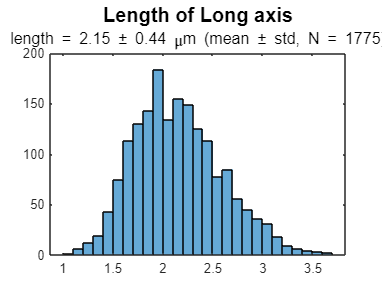

figure
str1 = { ['length = ' sprintf('%.2f ± %.2f', mean(Result_cat(:,2)), std(Result_cat(:,2))) ]};
str2 = {[' ' sprintf('(mean ± std, N = %d)', numel(Result_cat(:,2)))]};
str=append(str1,' \mu','m',str2);
histogram(Result_cat(:,2))
[t,s]=title('Length of Long axis',str);
t.FontSize=15;
s.FontSize=12;

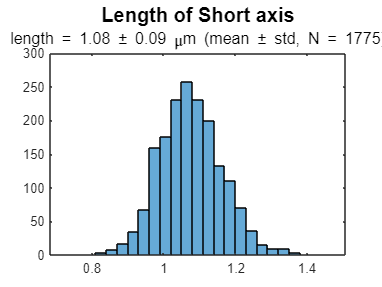


figure
% str = { [ 'length = ' sprintf('%.2f ± %.2f nm (mean ± std, N = %d)', mean(Result_cat(:,3)), std(Result_cat(:,3)), numel(Result_cat(:,3))) ] };
str1 = { ['length = ' sprintf('%.2f ± %.2f', mean(Result_cat(:,3)), std(Result_cat(:,3))) ]};
str2 = {[' ' sprintf('(mean ± std, N = %d)', numel(Result_cat(:,3)))]};
str=append(str1,' \mu','m',str2);
histogram(Result_cat(:,3))
[t,s]=title('Length of Short axis',str);
t.FontSize=15;
s.FontSize=12;

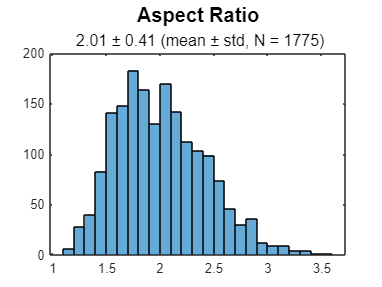


figure
% str = { [ ' ' sprintf('%.2f ± %.2f (mean ± std, N = %d)', mean(Result_cat(:,4)), std(Result_cat(:,4)), numel(Result_cat(:,4))) ] };
str1 = { [' ' sprintf('%.2f ± %.2f', mean(Result_cat(:,4)), std(Result_cat(:,4))) ]};
str2 = {[' ' sprintf('(mean ± std, N = %d)', numel(Result_cat(:,4)))]};
str=append(str1,str2);
histogram(Result_cat(:,4))
[t,s]=title('Aspect Ratio',str);
t.FontSize=15;
s.FontSize=12;

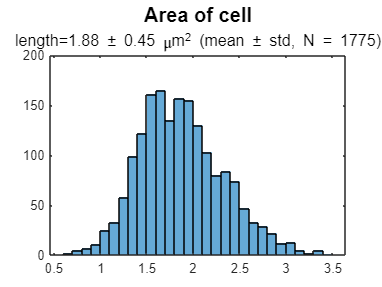


figure
% str = { [ 'Area = ' sprintf('%.2e ± %.2e nm^2 (mean ± std, N = %d)', mean(Result_cat(:,5)), std(Result_cat(:,5)), numel(Result_cat(:,5))) ] };
str1 = { ['length=' sprintf('%.2f ± %.2f', mean(Result_cat(:,5)), std(Result_cat(:,5))) ]};
str2 = {[' ' sprintf('(mean ± std, N = %d)', numel(Result_cat(:,5)))]};
str=append(str1,' {\mu}','m^2',str2);
histogram(Result_cat(:,5))
[t,s]=title('Area of cell',str);
s.FontSize=12;
t.FontSize=15;


clear s t str1 str2 str